%%Task 1
clc;
clear;

N=100;
L=25;
times=0;
theoreticalvalue=0.05;
X = L * rand(N,1);

for i=1:N
    if(X(i,1)>0.1*L&&X(i,1)<0.15*L)
    times=times+1;
    end
    
end
times %The experimental result

times = 1

difference=(times/100)-theoreticalvalue;
difference %The difference between the experimental result and the theoretical value

difference = -0.0400

M=100;
L=25;
m=zeros(M,1);
average=0;
var=0;

for j=1:M
    times=0;
    X=L*rand(N,1);
    for i=1:N
        if(X(i,1)>0.1*L&&X(i,1)<0.15*L)
            times=times+1;
        end
    end
    m(j,1)= times;
    average = average+(1/M)*(m(j,1)/N-0.05); %The average error
    var = var+((1/M)*(m(j,1)/N-0.05)^(2)); %The Variance
end
 average %The average error

average = 0.0011

 var %The Variance

var = 4.7300e-04

%%Task 2
%a
N=1000;
M=100;
L=25;
m=zeros(M,1);
average=0;
var=0;

for j=1:M
    times=0;
    X=L*rand(N,1);
    for i=1:N
        if(X(i,1)>0.1*L&&X(i,1)<0.15*L)
            times=times+1;
        end
    end
    m(j,1)= times;
    average = average+(1/M)*(m(j,1)/N-0.05); %The average error
    var = var+((1/M)*(m(j,1)/N-0.05)^(2)); %The Variance
end
 average %The average error

average = 1.1000e-04

 var %The Variance

var = 5.0590e-05

%b
N=10000;
M=100;
L=25;
m=zeros(M,1);
average=0;
var=0;

for j=1:M
    times=0;
    X=L*rand(N,1);
    for i=1:N
        if(X(i,1)>0.1*L&&X(i,1)<0.15*L)
            times=times+1;
        end
    end
    m(j,1)= times;
    average = average+(1/M)*(m(j,1)/N-0.05); %The average error
    var = var+((1/M)*(m(j,1)/N-0.05)^(2)); %The Variance
end
 average %The average error

average = -2.4818e-18

 var %The Variance

var = 4.8028e-06

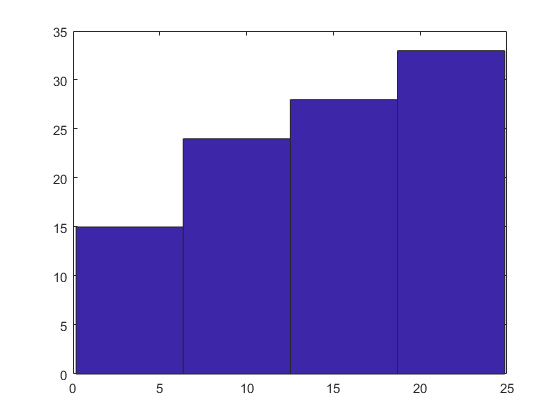

%%Task 3
%Q1
N=100;
L=25;
X = L * rand(N,1);
hist(X,4);

p=hist(X,4);
p

p =     15    24    28    33


mean(p)

ans = 25

clear var
var(p)

ans = 58

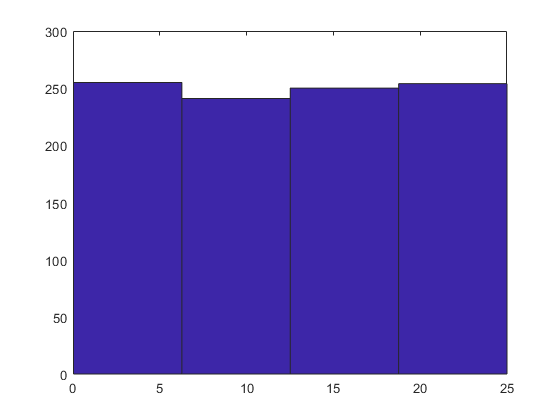

%%Task 3
%Q2
N=1000;
L=25;
X = L * rand(N,1);
hist(X,4);

p=hist(X,4);
p

p =    255   241   250   254


mean(p)

ans = 250

clear var
var(p)

ans = 40.6667

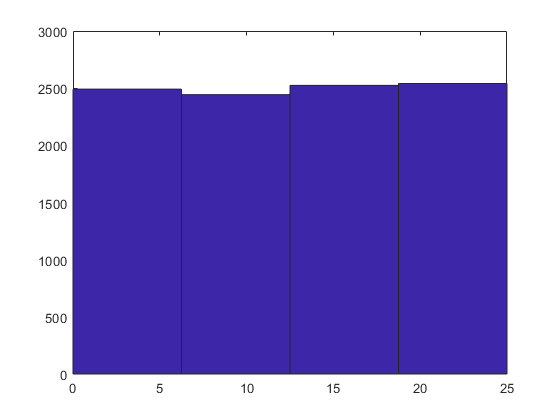

%%Task 3
%Q3
N=10000;
L=25;
X = L * rand(N,1);
hist(X,4);

p=hist(X,4);
p

p =         2492        2443        2524        2541


mean(p)

ans = 2500

clear var
var(p)

ans = 1.8567e+03